# Classification: Human Activity Recognition Using Mobile Phone Data

This is a supervised learning example. Human activity sensor data contains observations derived from sensor measurements taken from smartphones worn by people while doing six different activities: Walking, Sitting, Lying, Standing, Walking Upstairs, and Walking Downstairs.  The goal of this example is to build a classifier that can automatically identify the activity type given the sensor measurements.

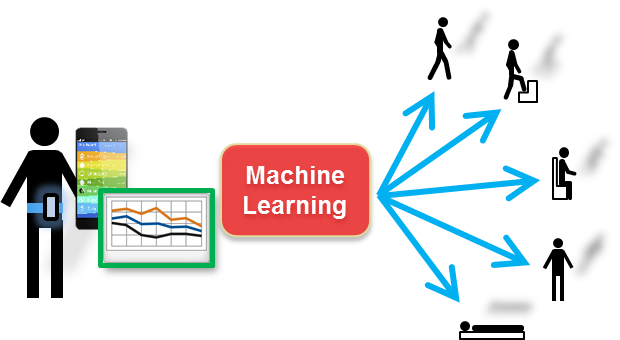

## 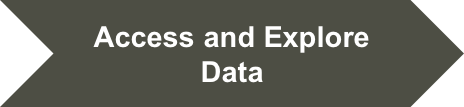

## Load Raw Sensor Data for Training

Data has been split and stored into two MAT files, one for training and one for testing. See data folder for addtional info on original files. 

Load raw data for training. The file contains 3-axial accelerometor and 3-axial gyroscope measurements for a total of 7352 subject activities recorded.

load('rawSensorData_train.mat')

## Display Data Summary

Display the original sensor data.

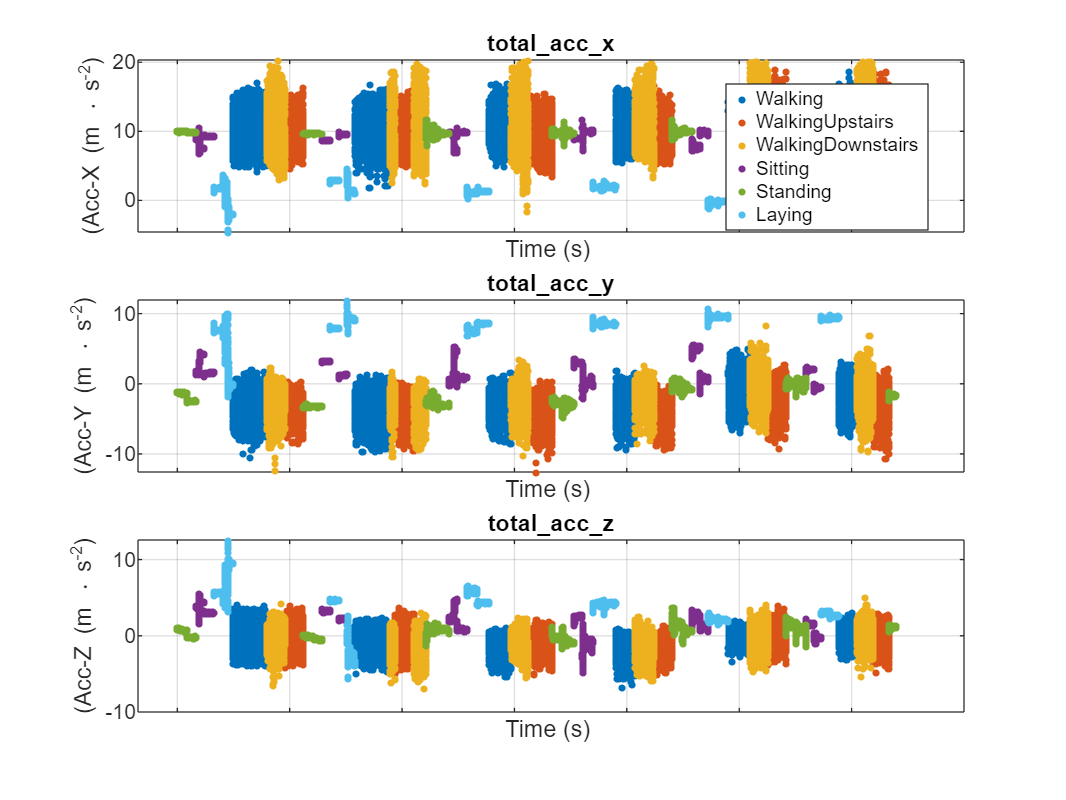

plotRawSensorData(total_acc_x,total_acc_y,total_acc_z,trainActivity,1000);

## 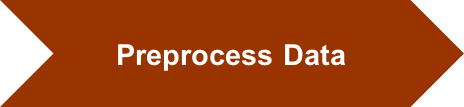

## Create Table Variable

Tables facilitate easy manipulation of lots of variables. Concatenate everything into a table.

rawSensorDataTrain = table(...
    total_acc_x, total_acc_y, total_acc_z, ...
    body_gyro_x, body_gyro_y, body_gyro_z)

rawSensorDataTrain = 7352×6 table
    total_acc_x     total_acc_y     total_acc_z     body_gyro_x     body_gyro_y     body_gyro_z 
    ____________    ____________    ____________    ____________    ____________    ____________
    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double
    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double
    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double
    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double
    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double
    1×128 double    1×128 double    1×128 double    1×128 double    1×128 double   

## Pre-Process Training Data: **Feature Extraction**

The sensor data contain windows of 2.56sec (128 readings/window) Let's start with some simple statistical features for every 128 points: mean, standard deviation, and the first principal component score.

T_mean = varfun(@rowmean, rawSensorDataTrain);
T_stdv = varfun(@rowstd, rawSensorDataTrain);
T_pca  = varfun(@pcascore, rawSensorDataTrain);

% Build new table
humanActivityData = [T_mean, T_stdv, T_pca];
humanActivityData.activity = trainActivity;

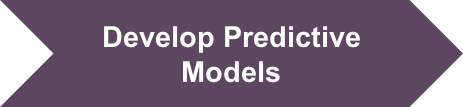 

## Train, Compare and Select Classifier 

Use the [Classification Learner App](matlab: web(fullfile(docroot, 'stats/classificationlearner-app.html'))) to interactively train, compare and select classifiers.  One of the biggest challenges in machine learning is there are many different machine learning algorithms that could be applied to the same problem, and there is no way of knowing ahead of time which will work best. The Classification Learner App gives us an easy way to try out many different modeling techniques very quickly.

- [Run the Classification Learner App](matlab:classificationLearner) with the `humanActivityData` dataset. 

- Export the best model you can find into the MATLAB Workspace.

- Use the exported model to make predictions on new data.  

or load previously trained classifier.

retrainOpt =false;
if retrainOpt
    trainedClassifier = trainFineKNNClassifier(humanActivityData);
else
    load('trainedClassifier.mat')
end

## Load Raw Sensor Data for Testing

Load test data set.

load('rawSensorData_test.mat')

## Test Classifier Performance On New Data

**Step 1: Create a table**

rawSensorDataTest = table(...
    total_acc_x, total_acc_y, total_acc_z, ...
    body_gyro_x, body_gyro_y, body_gyro_z);


**Step 2: Extract features from raw sensor data**

T_mean = varfun(@rowmean, rawSensorDataTest);
T_stdv = varfun(@rowstd, rawSensorDataTest);
T_pca  = varfun(@pcascore, rawSensorDataTest);

% Add data to human activity        
humanActivityDataTest = [T_mean, T_stdv, T_pca];
humanActivityDataTest.activity = testActivity;

**Step 3: Use trained model to predict activity on new sensor data**

% Split data into training and test data 
X = humanActivityData(:, 1:end-1); % Training
Y = humanActivityData.activity;
Xtest = humanActivityDataTest(:, 1:end-1); % Testing
Ytest = humanActivityDataTest.activity;

TestPredModel = predict(trainedClassifier, Xtest);

**Step 4: Show results with new data**

[Animate the activity results](matlab:ClassificationOpeningExample).

% Calculate Test Data Accuracy
accuracy = sum(testActivity==TestPredModel)/length(testActivity);
disp("Test Data Accuracy = "+100*accuracy+"%")
figure;
confusionchart(testActivity,TestPredModel,'Normalization','row-normalized')

## Optimize Hyperparameters

Again, we use a Fine KNN classifier but only using the features selected in the previous step. Hopefully, we get an as-good result in less time and using fewer columns of data.  

We will also optimize the model hyperparameters.  A hyperparameter is an internal parameter of a classifier or regression function, and each learning algorithm has different hyperparameters to optimize.  For Fine KNN, these include parameters such as Distance Metric and Number of Neighbors.  These parameters can strongly affect the performance of a classifier or regressor, and yet it is typically difficult or time-consuming to optimize them. Bayesian optimization is well-suited to optimizing hyperparameters of classification and regression algorithms.  

retrainOpt =false;
if retrainOpt
    optimizedClassifier = fitcknn(X, Y, 'Distance', ...
       'Euclidean', 'Exponent', '', 'NumNeighbors', 1, ...
       'DistanceWeight', 'Equal', 'StandardizeData', 1, ...
       'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', ...
       struct('UseParallel', true));
else
    load('trainedOptimized.mat')
end



Use new model for predictions and calculate accuracy.

TestPred = predict(optimizedClassifier, Xtest);
accuracy = sum(testActivity==TestPred)/length(testActivity);
disp("Test Data Accuracy = "+100*accuracy+"%")
figure;
confusionchart(Ytest, TestPred, 'Normalization', 'row-normalized');

We can see that optimizing the hyperparameters of the Fine KNN algorithm resulted in a slight increase in test prediction accuracy.

## Automated Machine Learning (AutoML) with Hyperparameter Optimization (Optional)

In R2020a, alternatively, we can automatically select a classification model with optimized hyperparameters using the "[fitcauto](matlab: web(fullfile(docroot, 'stats/fitcauto.html')))" function in order to improve classifier performance.

retrainAuto = false;

if retrainAuto
    trainedAutoML = fitcauto(humanActivityData,'activity','HyperparameterOptimizationOptions',struct('UseParallel',true));
else
    load('trainedAutoML.mat')
end

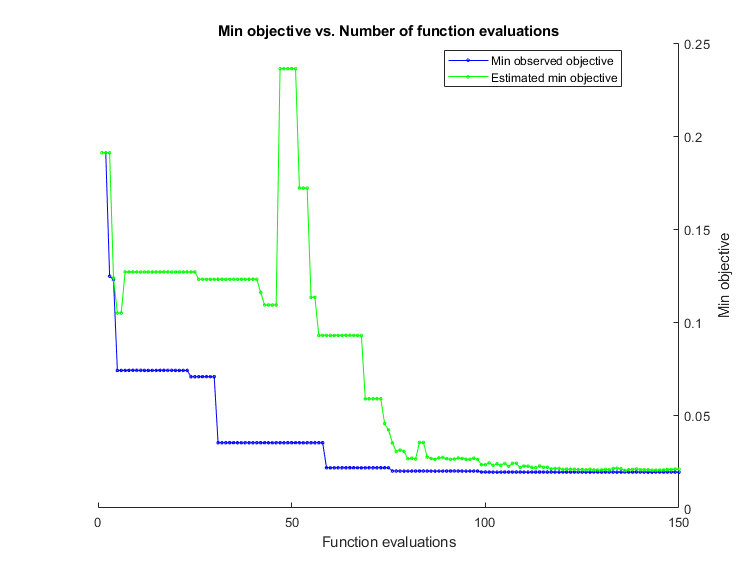

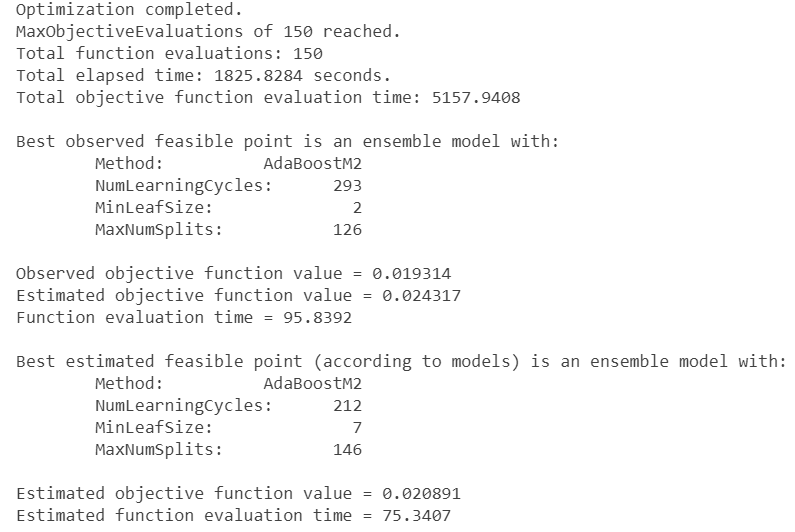

Use new model for predictions and calculate accuracy.

TestPredAuto = predict(trainedAutoML, Xtest);
accuracy = sum(testActivity==TestPredAuto)/length(testActivity);
disp("Test Data Accuracy = " + 100*accuracy + "%")
figure;
confusionchart(Ytest, TestPredAuto, 'Normalization', 'row-normalized');

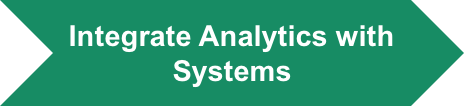

## Code Generation

Generate C code that takes sensor data as input and produces an activity classification label as output.  First we save the model and features for coder.

A new model is trained that uses code generation compatible functionality. We load the compact model generated from the Classification Learner.

load('codeGenModel.mat')


% Use selected features for deployed model
kpFeatures = logical([1 1 0 0 0 1 1 1 1 1 1 1 1 1 1 0 0 0]);
p = size(X, 2);
x = coder.typeof(0, [Inf p], [1 0]);
testSample = table2array(Xtest);

We generate a MEX to use C code directly in MATLAB.  Open [MATLAB Coder App.](matlab:coder)

regeneratecode = false;
if regeneratecode
    codegen("predictActKnn.prj")
end

## Validate Final Model

Verify that generated code gives the same results as model in MATLAB.

Predict with test data using MEX

testResults = predictActKnn_mex(testSample); 

Predict with test data using previously trained model

testFinalPred = trainedModel.predictFcn(testSample);

Compare results of generated C code with trained MATLAB model.

disp((sum(testFinalPred==testResults)/length(testFinalPred)))